n = 500;
Q = orth(randn(n,n));
d = logspace(0, -10, n);
A = Q*diag(d)*Q';
x = randn(n, 1);
b = A*x;
tic, y = inv(A)*b; toc

Elapsed time is 0.004357 seconds.


err = norm(y-x);
err

err =      3.210653594583905e-06


res = norm(A*y-b);
res

res =      3.345050369672784e-07



%pause

tic, z = A\b; toc

Elapsed time is 0.003338 seconds.


err = norm(z-x);
err

err =      3.194745111009851e-06


res = norm(A*z - b);
res

res =      2.602592860183635e-15



%pause

A = randn(4,4);

% inv function
disp("Inv Function")

Inv Function


y = inv(A)

y =   -0.409890273834118   1.694338098868624   4.618651188102351   2.104886707484246
   0.441779289172520   2.159570842737097   5.932360108985948   3.543150011692573
   0.152312032061568   2.111613280096078   4.210132389346296   2.993647408177920
  -0.110910965828088  -2.886512953179504  -6.736050438047637  -3.612258730884117



norm(eye(4,4) - A*y)

ans =      4.155340669817864e-15



% mldivide function
disp("mldivide")

mldivide


b = eye(4,4);
y = A \ b

y =   -0.409890273834118   1.694338098868624   4.618651188102352   2.104886707484247
   0.441779289172520   2.159570842737097   5.932360108985949   3.543150011692573
   0.152312032061568   2.111613280096078   4.210132389346296   2.993647408177920
  -0.110910965828088  -2.886512953179504  -6.736050438047637  -3.612258730884117



norm(eye(4,4) - A*y)

ans =      1.281169576270751e-15



% mrdivide function
disp("mrdivide")

mrdivide


B = eye(4,4);
y = B/A

y =   -0.409890273834118   1.694338098868625   4.618651188102354   2.104886707484248
   0.441779289172520   2.159570842737097   5.932360108985948   3.543150011692572
   0.152312032061568   2.111613280096078   4.210132389346296   2.993647408177920
  -0.110910965828088  -2.886512953179504  -6.736050438047637  -3.612258730884117



norm(eye(4,4) - A*y)

ans =      4.107223458387826e-15



% s is for read file
% c is for running files, don't save on c drive
% w for backup
% for rail system, to stop it, run an empty arduino file

%%% Eigenvectors Eigenvalues
format short
disp("Eigenvector Section")

Eigenvector Section


disp("Normal")

Normal


A = [7 2 -3; 4 6 -4; 5 2 -1]

A =      7     2    -3
     4     6    -4
     5     2    -1


[V,D] = eig(A)

V =     0.2673    0.5774    0.7071
    0.5345    0.5774   -0.0000
    0.8018    0.5774    0.7071


D =     2.0000         0         0
         0    6.0000         0
         0         0    4.0000



disp("Integers")

Integers


[V,D] = eig(A,'nobalance')

V =     0.2673    0.5774    0.7071
    0.5345    0.5774   -0.0000
    0.8018    0.5774    0.7071


D =     2.0000         0         0
         0    6.0000         0
         0         0    4.0000



% Divide the column by its first entry

% Characterstic Polynomial
Characterstic = poly(A)

Characterstic =     1.0000  -12.0000   44.0000  -48.0000


roots(Characterstic)

ans =     6.0000
    4.0000
    2.0000



% AV = VD
disp("Before")

Before


norm(A*V-V*D)

ans = 2.4534e-15


V = [1 1 1; 2 1 0; 3 1 1];
D = [2 0 0; 0 6 0; 0 0 4];
format long

disp("After")

After


norm(A*V-V*D)

ans =      0



% Diagonalizable
disp("Diagonalizable error")

Diagonalizable error


disp(D)

     2     0     0
     0     6     0
     0     0     4



disp(V\A*V)

   2.000000000000000   0.000000000000000   0.000000000000000
                   0   5.999999999999999                   0
                   0  -0.000000000000000   4.000000000000000



norm((V\A)*V - D)

ans =      1.114515235418803e-15



% Basically diagonalizable

% Multiplicity
disp("Multiplicity")

Multiplicity


A = [1 1; 0 1];
[V,D] = eig(A)

V =    1.000000000000000  -1.000000000000000
                   0   0.000000000000000


D =      1     0
     0     1



disp(D)

     1     0
     0     1



disp(V\A*V)

   1.000000000000000   0.000000000000000
                   0   1.000000000000000



norm((V\A)*V - D)

ans =      2.220446049250313e-16



% Jordan
A = [0 4 3; 0 20 16; 0 -25 -20]

A =      0     4     3
     0    20    16
     0   -25   -20


jordan(A)

ans =      0     1     0
     0     0     1
     0     0     0


%%% Ordinary Differential Equation
disp("ODE")

ODE


A = [0 1; -4 -2];
B = [0;4];
C = [1 0];
D = [0];
sys=ss(A,B,C,D)

sys =
 
  A = 
       x1  x2
   x1   0   1
   x2  -4  -2
 
  B = 
       u1
   x1   0
   x2   4
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



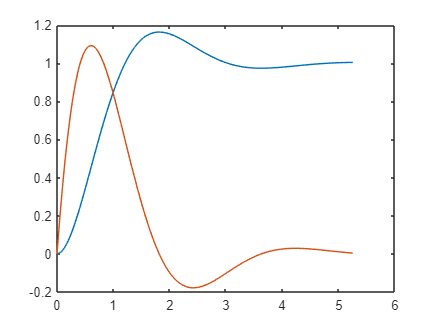


[Y,T,X] = step(sys);
plot(T,X)

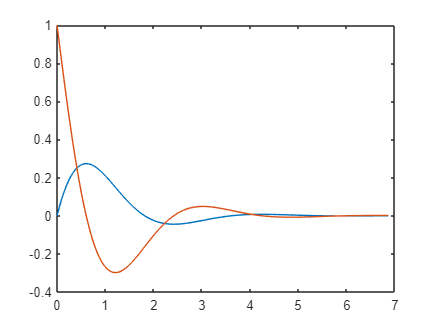


x0 = [0;1];
sys_init = ss(A,[0;0],C,[0]);
[Y,T,X] = initial(sys_init,x0);
plot(T,X)

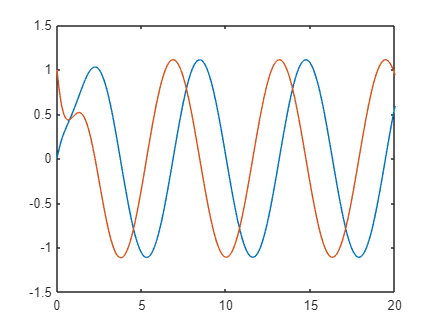


% New system
t = 0:0.01:20;
u = sin(t);

% blue line is x, orange line is derivative
[Y, t, X] = lsim(sys, u, t, x0);
plot(t,X)


% part e)
[numerator,denominator] = ss2tf(A,B,C,D)

numerator =      0     0     4


denominator =    1.000000000000000   2.000000000000000   3.999999999999999


tf(numerator,denominator)

ans =
 
        4
  -------------
  s^2 + 2 s + 4
 
Continuous-time transfer function.

